%This is the Start of Nathan Faber and Stella Stark's Code for Project 2
%Calibrating and Fitting our Measured Data
clf
dinch = [48 45 42 39 36 33 30 27 24 21 18 17 16 15 14 13 12 11 10 9 8 7 6 5]; %Measured Distances
d = dinch/39.37; % gives distance in meters
drOutput = [107 112 122 133 145 158 171 193 216 243 293 315 326 335 360 375 400 430 460 490 520 532 560 564]; %Measured Output
p = polyfit(drOutput,d,4); % gives coefficiants in a fourth order fitted curve equation that outputs d
drOutput2 = 107:19.87:564.01; % gives consistent values to plot our p curve onto
d2 = polyval(p,drOutput2); % gives fitted distance values using the equation defined in p
%plot graphs


errorData =     23   219
    21   236
    19   263
    17   298
    15   342
    13   391
     6   560


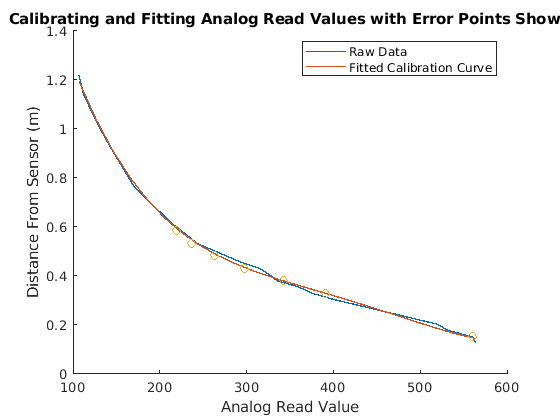

hold on
    plot(drOutput, d,"LineWidth",1) %plot raw data
    plot(drOutput2,d2, "LineWidth",1) %plot fitted data
    plot( errorData(:,2), errorData(:,1)/39.37, "o")
    xlabel("Analog Read Value")
    ylabel("Distance From Sensor (m)")
    legend ('Raw Data','Fitted Calibration Curve')
    title("Calibrating and Fitting Analog Read Values")
hold off

clear s
freeports = serialportlist("available") % Shows available serial ports

freeports = "/dev/ttyS4"

%
port = "/dev/ttyACM0"%Choose which port to use for Arduino (proabably best to hardcode)

port = "/dev/ttyACM0"

baudrate = 9600;
s = serialport(port,baudrate);

Error using serialport (line 116)
Unable to connect to the serialport device at port '/dev/ttyACM0'. Verify that a device is connected to the port, the port is not in use, and all serialport input arguments and parameter values are supported by the device.
Additional Information: Unexpected exception in plug-in: 'open: No such file or directory'

q = 0
values = NaN(1,4);
%initialize a timeout in case MATLAB cannot connect to the arduino
timeout = 0;
% main loop to read data from the Arduino, then display it%
while timeout < 10    %    % check if data was received    %    
    while s.NumBytesAvailable > 0     
        timeout = 0;        
        %        
        % data was received, convert it into array of integers        
        %        
        value = eval(strcat('[',readline(s),']'));              
        a = value(1);        
        b = value(2);        
        c = value(3);        
        d = value(4);          
        disp(sprintf('a,b,c,d = %d,%d,%d,%d\n',[a,b,c,d]));
        q = q + 1;
        values(q,:) = [a b c d];
    end
    pause(0.5);    
    timeout = timeout + 1;
end
clear s;

% Turn Analog Read value into (x,y,z) coordinates
% I want to plot this is 3d
% Want to use mesh grid
% make sure that readings outside of our set range get filtered out
% use D = polyval (p, input from monitor)
coords = NaN(1,6);
for i = 1:length(values)
    pan = values(i,1);
    tilt = values(i,2);
    dist = polyval(p,values(i,3));
    x = dist*cosd(pan)*cosd(tilt);
    y = dist*sind(pan)*cosd(tilt);
    z = dist*sind(tilt);
    coords(i,:) = [x y z pan tilt dist];
end


## Vector math

% Conversion from Polar to Cartesian Coordinates
distance = polyval(p,values(:,3));
scat(:,1) = distance(:,1).* cosd(values(:,1)).*cosd(values(:,2));
scat(:,2) = distance(:,1).* sind(values(:,1)).*cosd(values(:,2));
scat(:,3) = distance(:,1).* sind(values(:,2));

%plot in 3d the points
clf
hold on
scatter3(coords(:,1), coords(:,2), coords(:,3),'filled')
axis equal
hold off

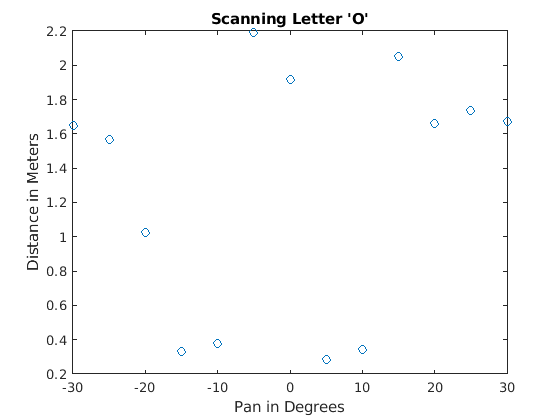

plot(coords(:,4), coords(:,6), "o")
title("Scanning Letter 'O'")
xlabel("Pan in Degrees")
ylabel("Distance in Meters")

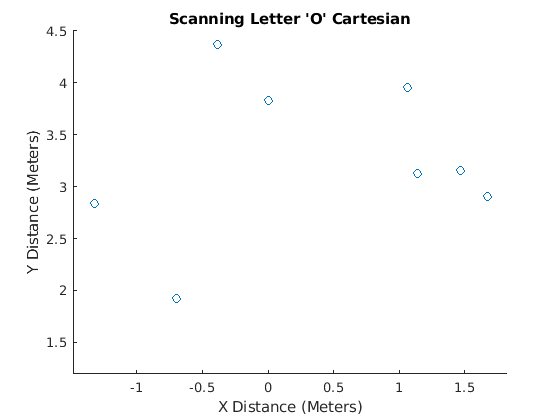


scatter(coords(:,2), coords(:,1));
title("Scanning Letter 'O' Cartesian")
xlabel("X Distance (Meters)")
ylabel("Y Distance (Meters)")

% Generate error graph
% Other data not in plot
errorData = [23,219;
             21, 236;
             19, 263;
             17, 298;
             15, 342;
             13, 391;
             6, 560]

errorData =     23   219
    21   236
    19   263
    17   298
    15   342
    13   391
     6   560


errorData(:,3) = errorData(:,1)/39.37

errorData =    23.0000  219.0000    0.5842
   21.0000  236.0000    0.5334
   19.0000  263.0000    0.4826
   17.0000  298.0000    0.4318
   15.0000  342.0000    0.3810
   13.0000  391.0000    0.3302
    6.0000  560.0000    0.1524


errorData(:,4) = polyval(p,errorData(:,2))

errorData =    23.0000  219.0000    0.5842    0.5950
   21.0000  236.0000    0.5334    0.5492
   19.0000  263.0000    0.4826    0.4909
   17.0000  298.0000    0.4318    0.4343
   15.0000  342.0000    0.3810    0.3808
   13.0000  391.0000    0.3302    0.3294
    6.0000  560.0000    0.1524    0.1480


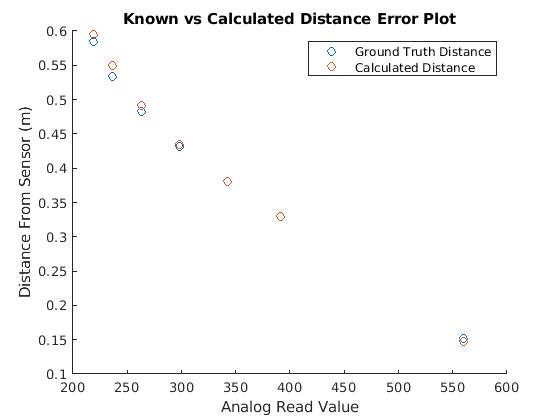

clf
hold on
scatter(errorData(:, 2), errorData(:, 3));
scatter(errorData(:, 2), errorData(:, 4));
xlabel("Analog Read Value")
ylabel("Distance From Sensor (m)")
legend ('Ground Truth Distance','Calculated Distance')
title("Known vs Calculated Distance Error Plot")

hold off